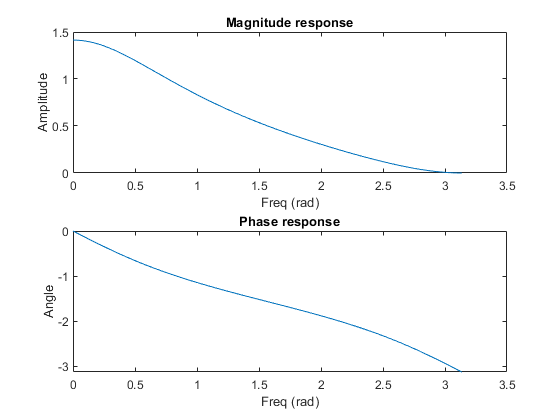

clear all;clc;close all;
 
B = [0.2929	0.5858    0.2929];
A = [1.0000    0	   -0.1716];
N = 512;
[H,W] = freqz(B,A,N) ;
 
figure(1);
subplot(211);plot(W,abs(H)); %% plot abs of complex

title('Magnitude response');
xlabel('Freq (rad)');ylabel('Amplitude');
 
subplot(212);plot(W,angle(H)); %% plot phase of complex
title('Phase response');
xlabel('Freq (rad)');ylabel('Angle');

h=impz(B,A)

h =     0.2929
    0.5858
    0.3432
    0.1005
    0.0589
    0.0172
    0.0101
    0.0030
    0.0017
    0.0005


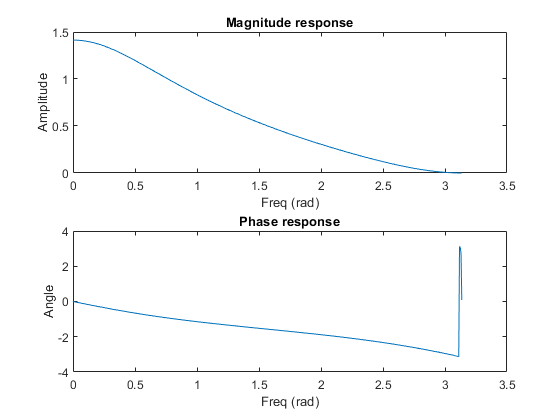

[H,W] = freqz(h,1,N);
 
figure;
subplot(211);plot(W,abs(H)); %% plot abs of complex
title('Magnitude response');
xlabel('Freq (rad)');ylabel('Amplitude');
 
subplot(212);plot(W,angle(H)); %% plot phase of complex
title('Phase response');
xlabel('Freq (rad)');ylabel('Angle');

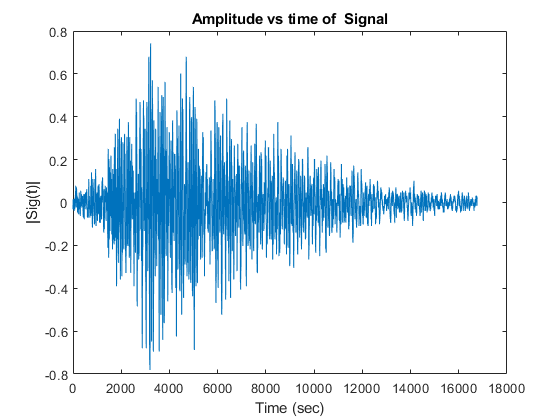

clear all;
[sig fs]=audioread('tiger.wav');
figure;
t=1:length(sig)/fs;
plot(sig);
title('Amplitude vs time of  Signal')
xlabel('Time (sec)')
ylabel('|Sig(t)|')

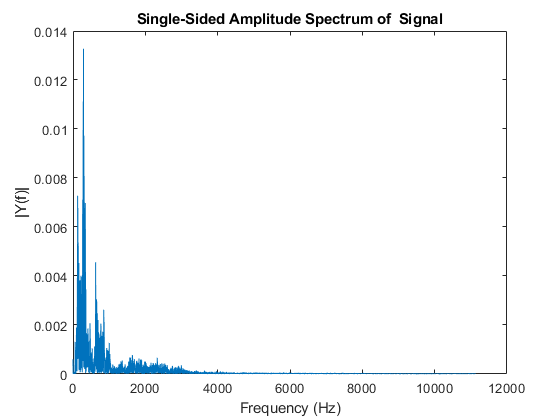

[Y F]=dtft(sig,fs);
figure;
plot(F,abs(Y));
title('Single-Sided Amplitude Spectrum of  Signal')
xlabel('Frequency (Hz)')
ylabel('|Y(f)|')